## Construction of Root Locus Diagram

### definition of the transfer funcition  

close all
clear;
num = [2 1];   % defining numinator 
denum = [1 3 2 0];  % defining denuminator 
G = tf(num,denum)  % defining the transfer function

G =
 
       2 s + 1
  -----------------
  s^3 + 3 s^2 + 2 s
 
Continuous-time transfer function.
Model Properties


step response of the initial system

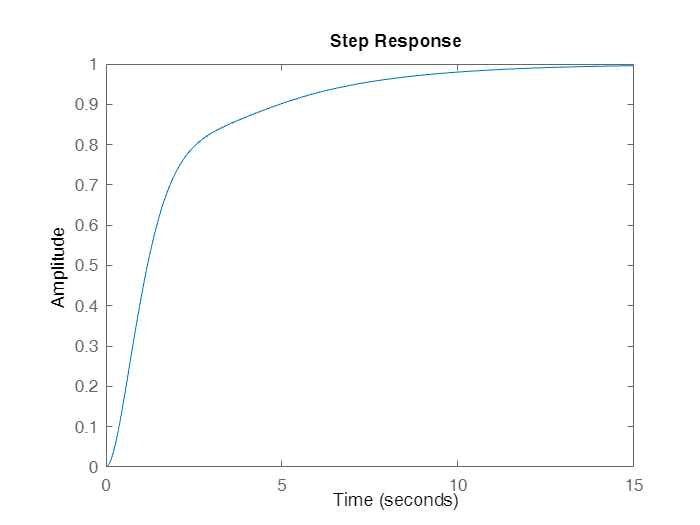

step(G/(1+G))

stepinfo(G/(1+G))

ans = struct with fields:
         RiseTime: 4.5641
    TransientTime: 9.9974
     SettlingTime: 9.9974
      SettlingMin: 0.9003
      SettlingMax: 0.9983
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9983
         PeakTime: 17.7866


### root locus 

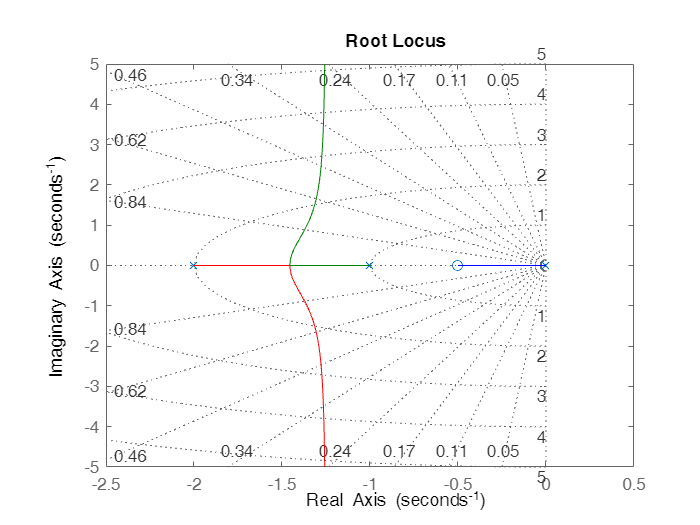

rlocus(G);
sgrid

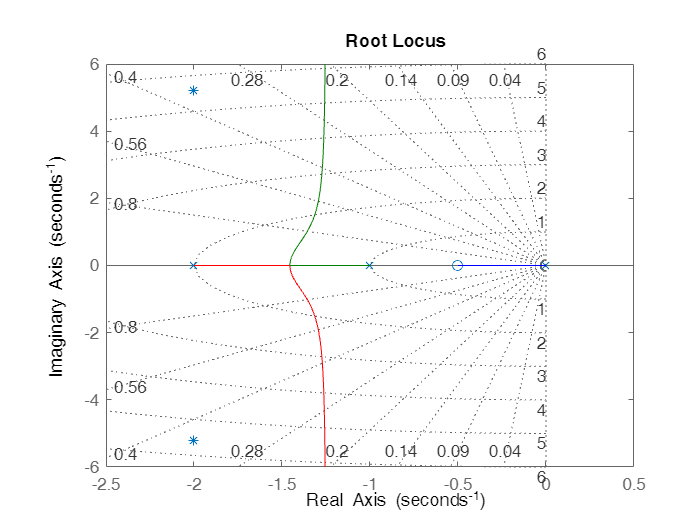

% root locus with desired poles 
figure();
rlocus(G);
hold on 
points = [-2 + 5.2j , -2-5.2j];
plot(points,'*')
sgrid
hold off

## Phase Lead Controller Design 

### Graphical Method 

pole(G) % poles of the transfer function 

ans =      0
    -2
    -1


zero(G) % zeros of the transfer function 

ans = -0.5000

% calculating the zetha , Wn and tp

Mp = log(0.3);
zetha = -Mp/sqrt(Mp^2+pi^2)

zetha = 0.3579

tp = 2;
% tp = 4/Wn(zetha)
Wn = 4/(tp*zetha)

Wn = 5.5888

betaa = acos(zetha);
betaa = rad2deg(betaa)

betaa = 69.0313

 Wn * sin(deg2rad(betaa))

ans = 5.2187

 s = -2 + 5.2i

s = -2.0000 + 5.2000i

determine the gain of the controller 

 num1 = s*(s+1)*(s+2)*(s+6.72);
 denum1 = (2*s+1)*(s+4.6);
 k1 = abs(num1/denum1)

k1 = 17.1202

 sys_gm_den = [1 9.63 21.89 13.26 0]; % Denominator using graphical method 
 sys_gm_num = [2 10.1 4.55]; % Numerator using graphical method
 tf_gm_sys = tf(sys_gm_num, sys_gm_den)% System transfer function 

tf_gm_sys =
 
         2 s^2 + 10.1 s + 4.55
  ------------------------------------
  s^4 + 9.63 s^3 + 21.89 s^2 + 13.26 s
 
Continuous-time transfer function.
Model Properties


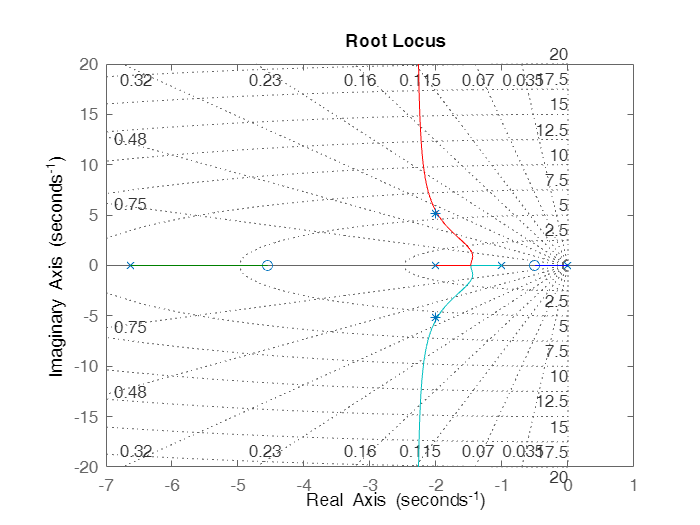

 figure()
 rlocus(tf_gm_sys)
 hold on 
 points = [-2 + 5.2j , -2-5.2j];
 plot(points,'*')
 sgrid
 hold off

step response

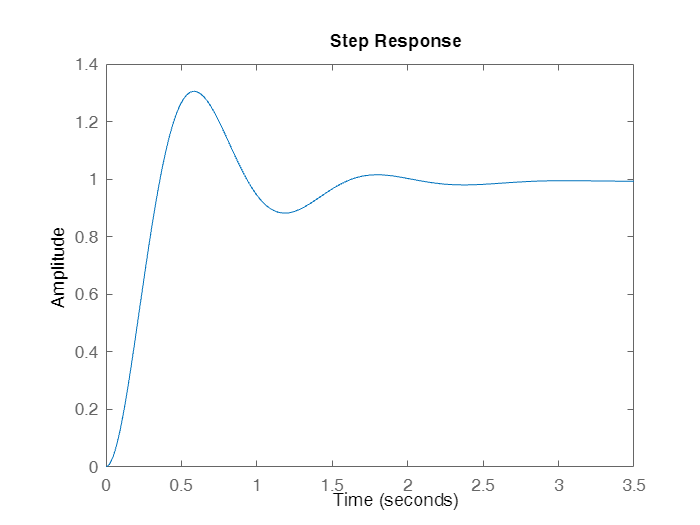

 sys = k1*tf_gm_sys/(1+k1*tf_gm_sys);
 step(sys)

 stepinfo(sys)

ans = struct with fields:
         RiseTime: 0.2429
    TransientTime: 2.3883
     SettlingTime: 2.3883
      SettlingMin: 0.8819
      SettlingMax: 1.3054
        Overshoot: 30.5420
       Undershoot: 0
             Peak: 1.3054
         PeakTime: 0.5795


### Pole Placement method 

 sys_pp_den = [1 4.47 3.47 0];
 sys_pp_num = [2 1];
 tf_sys_pp = tf(sys_pp_num, sys_pp_den)

tf_sys_pp =
 
          2 s + 1
  -----------------------
  s^3 + 4.47 s^2 + 3.47 s
 
Continuous-time transfer function.
Model Properties


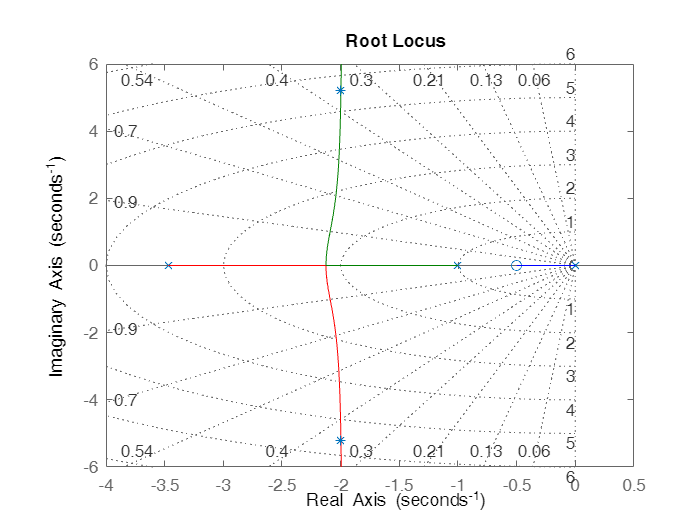

 rlocus(tf_sys_pp)
 hold on 
 points = [-2 + 5.2j , -2-5.2j];
 plot(points,'*')
 sgrid
 hold off

### Step Response 

 num2 = s*(s+1)*(s+3.47);
 denum2 = (2*s+1);
 k2 = abs(num2/denum2)

k2 = 14.7285

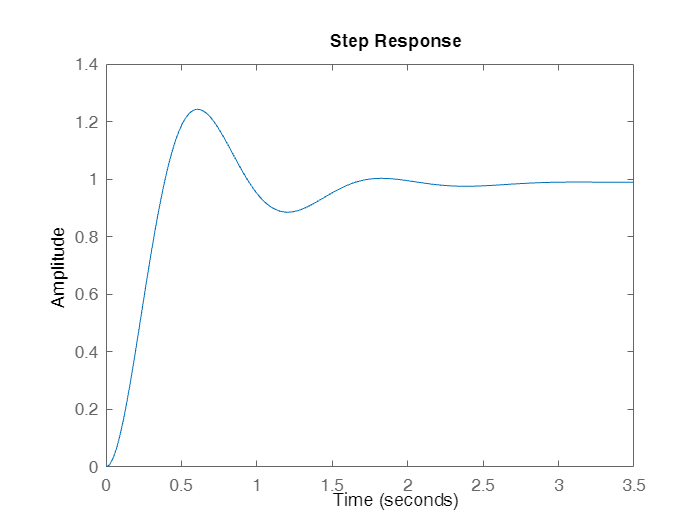

 sys2 = k2*tf_sys_pp/(1+k2*tf_sys_pp);
 step(sys2)

 stepinfo(sys2)

ans = struct with fields:
         RiseTime: 0.2650
    TransientTime: 2.6093
     SettlingTime: 2.6093
      SettlingMin: 0.8851
      SettlingMax: 1.2426
        Overshoot: 24.2624
       Undershoot: 0
             Peak: 1.2426
         PeakTime: 0.5994


## Phase Lag Controller 

 pl_gm_controller = tf([1 0.049],[1 0.0069])

pl_gm_controller =
 
  s + 0.049
  ----------
  s + 0.0069
 
Continuous-time transfer function.
Model Properties


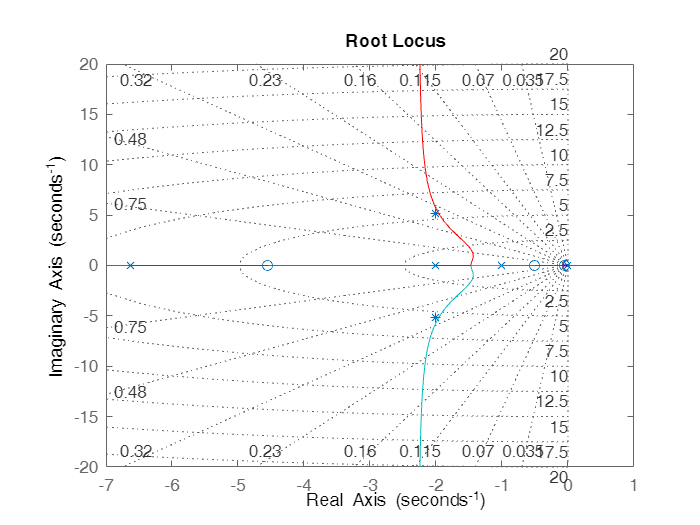

sys3 = tf_gm_sys*pl_gm_controller;
rlocus(sys3)
hold on 
points = [-2 + 5.2j , -2-5.2j];
plot(points,'*',"linewidth",0.5)
sgrid
hold off

Select a point in the graphics window


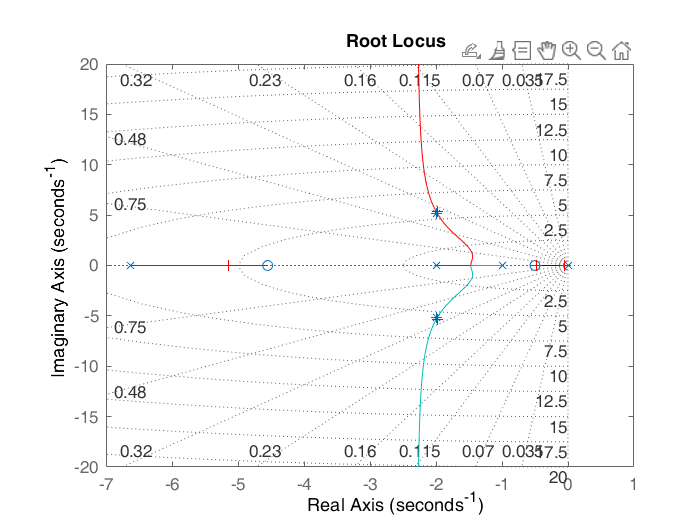

selected_point = -1.9924 + 5.3598i

k3 = 17.9634

k3 = rlocfind(sys3)

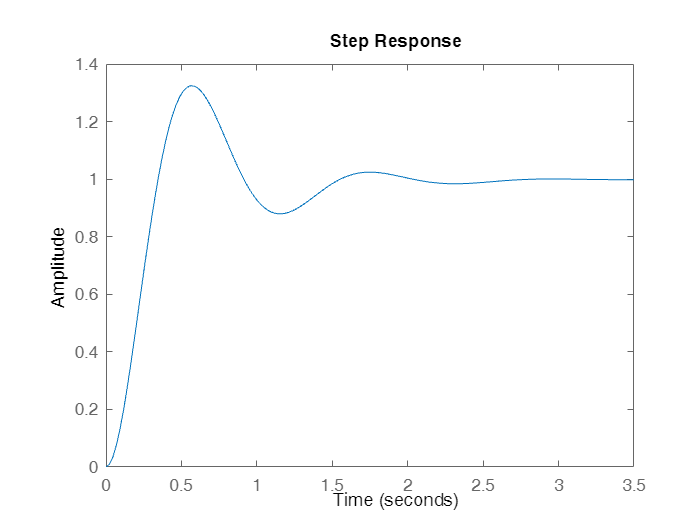


temp = k3*sys3/(1+k3*sys3);
step(temp)

stepinfo(temp)

ans = struct with fields:
         RiseTime: 0.2340
    TransientTime: 1.8463
     SettlingTime: 1.8463
      SettlingMin: 0.8796
      SettlingMax: 1.3242
        Overshoot: 32.4233
       Undershoot: 0
             Peak: 1.3242
         PeakTime: 0.5591


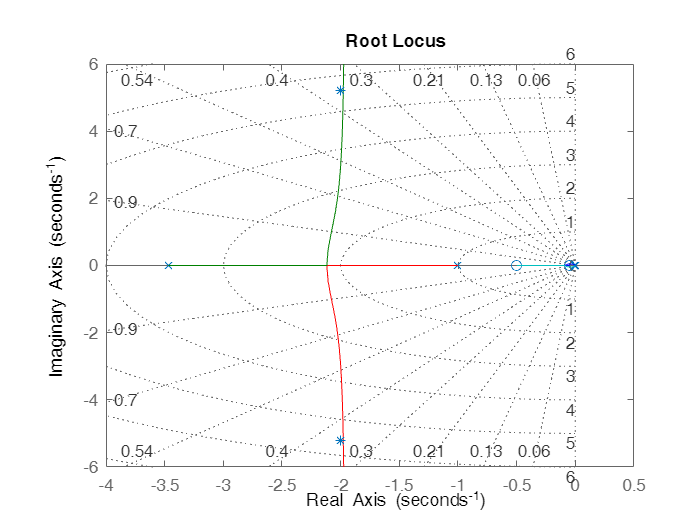

pl_pp_controller = tf([1 0.047],[1 0.0050]);
sys4 = pl_pp_controller * tf_sys_pp;
rlocus(sys4)
hold on 
points = [-2 + 5.2j , -2-5.2j];
plot(points,'*',"linewidth",0.5)
sgrid
hold off

Select a point in the graphics window


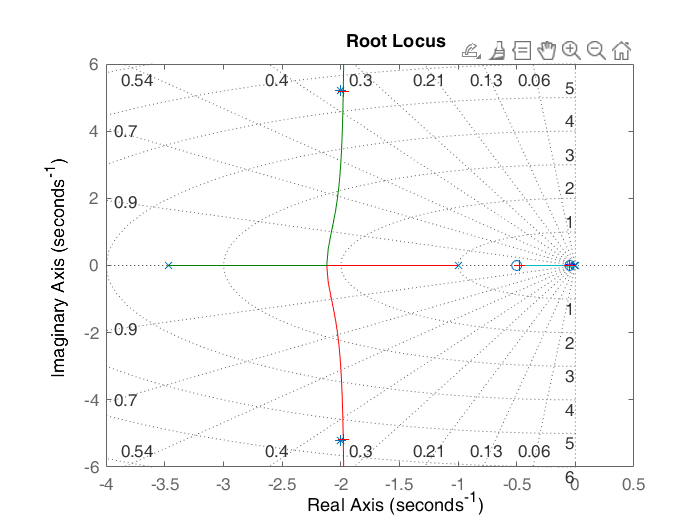

selected_point = -1.9759 + 5.1811i

k4 = 14.6704

k4 = rlocfind(sys4)

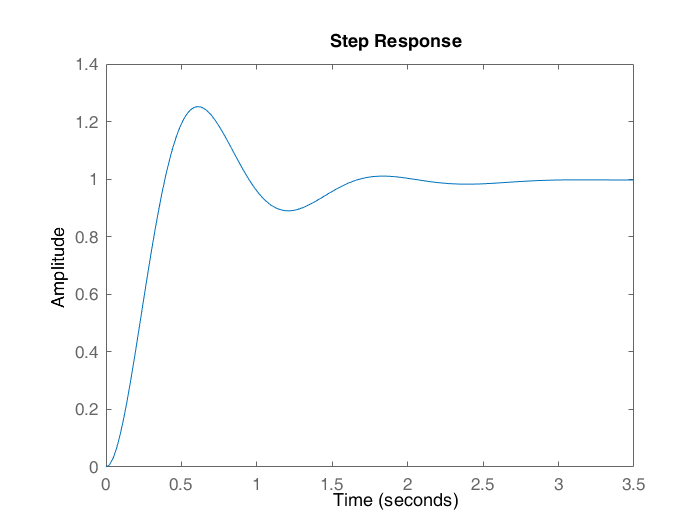

temp = k4*sys4/(1+k4*sys4);
step(temp)

)

stepinfo(temp)

ans = struct with fields:
         RiseTime: 0.2641
    TransientTime: 1.5807
     SettlingTime: 1.5807
      SettlingMin: 0.8899
      SettlingMax: 1.2520
        Overshoot: 25.2034
       Undershoot: 0
             Peak: 1.2520
         PeakTime: 0.6054
